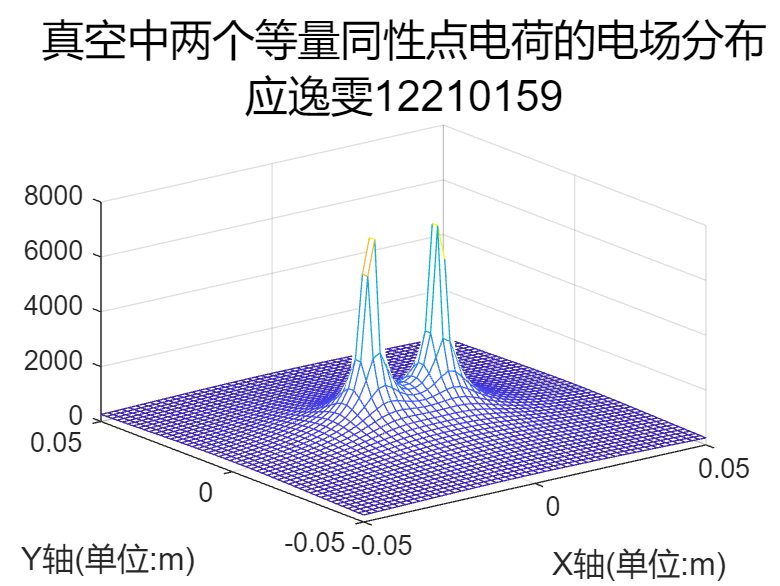

clc,clear,close all;
%两个等量同性点电荷的电场分布
%选择场域范围
k=9e9;
Q=1e-9;
Q2=1e-9;
xm=0.05;
ym=0.05;
x=linspace(-xm,xm,50);
y=linspace(-ym,ym,50);
[X,Y]=meshgrid(x,y);
%计算各点电位
R1=sqrt((X+0.01).^2+Y.^2);
R2=sqrt((X-0.01).^2+Y.^2);
V=k*Q./R1+k*Q2./R2;
%绘制各点电位分布
figure;
mesh(X,Y,V);
hold on;
%图表注释
title('真空中两个等量同性点电荷的电场分布','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图1-1.jpg');

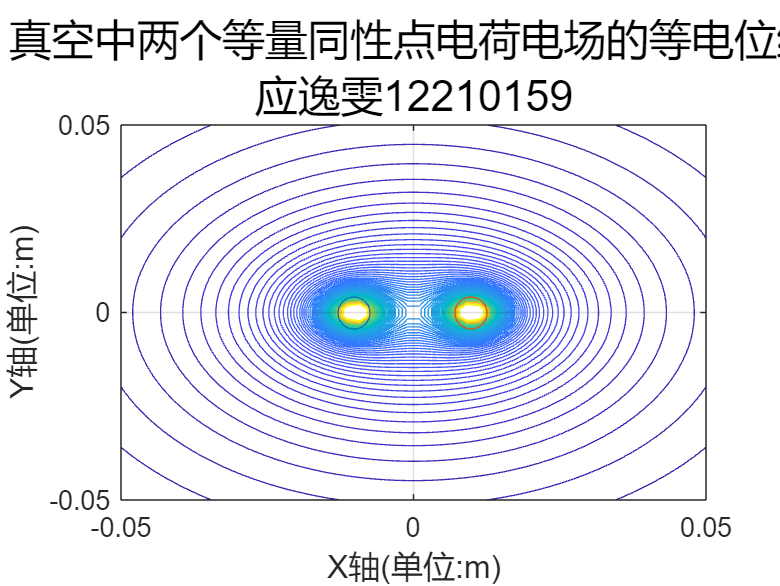

%选择合适的等电位值
Vmin=200;
Vmax=5000;
Veq=linspace(Vmin,Vmax,101);
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);
grid on;
hold on;
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title('真空中两个等量同性点电荷电场的等电位线','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图1-2.jpg');

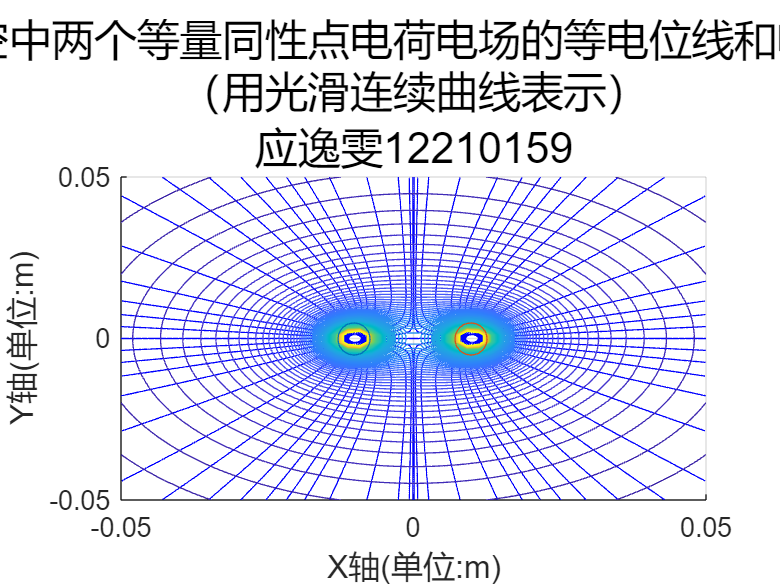

%计算电场线
[Ex,Ey]=gradient(-V);
del_theta=10;
theta=(0:del_theta:360).*pi/180;
xs1=-0.01+0.001*cos(theta);
xs2=0.01+0.001*cos(theta);
ys1=0.001*sin(theta);
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex,Ey,xs2,ys1);
grid on;
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量同性点电荷电场的等电位线和电力线\n（用光滑连续曲线表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图1-3.jpg');

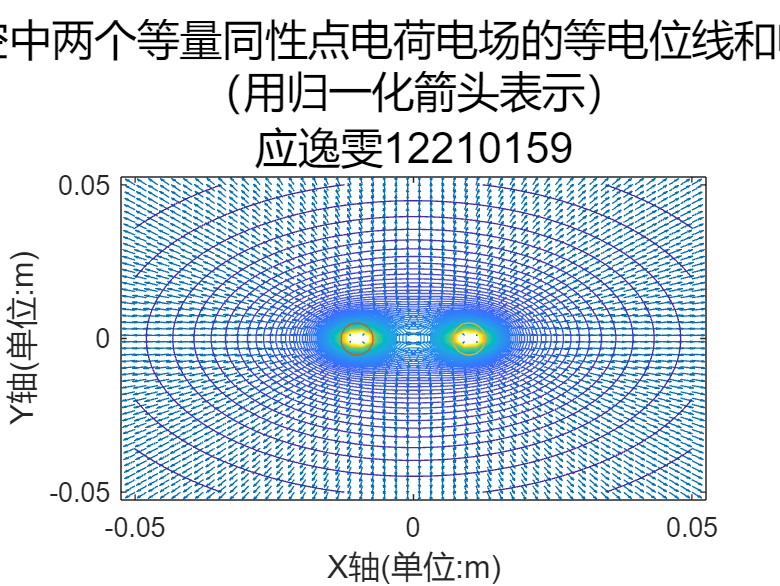

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);
Ex=Ex./E;
Ey=Ey./E;
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量同性点电荷电场的等电位线和电力线\n（用归一化箭头表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图1-4.jpg');

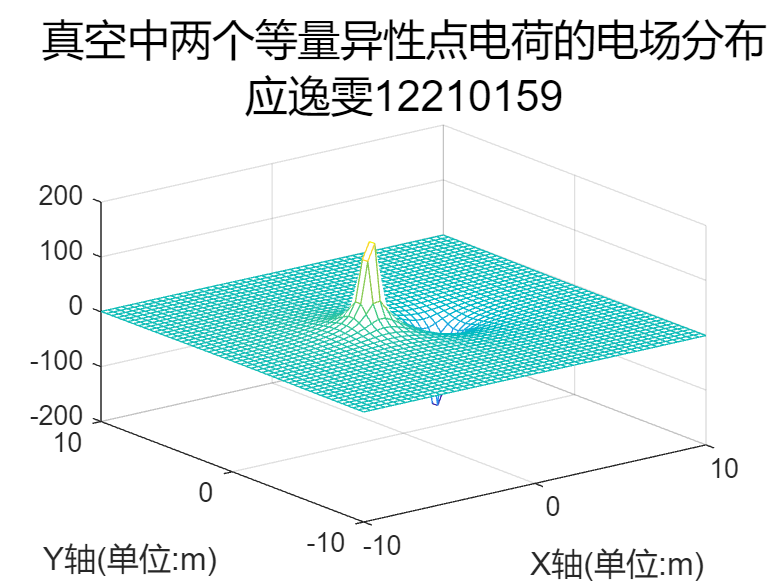

clc,clear,close all;
%两个等量异性点电荷的电场分布
%选择场域范围
k=9e9;
Q=5e-9;
Q2=-5e-9;
xm=10;
ym=10;
x=linspace(-xm,xm,50);
y=linspace(-ym,ym,50);
[X,Y]=meshgrid(x,y);
%计算各点电位
R1=sqrt((X+2).^2+Y.^2);
R2=sqrt((X-2).^2+Y.^2);
V=k*Q./R1+k*Q2./R2;
%绘制各点电位分布
figure;
mesh(X,Y,V);
hold on;
%图表注释
title('真空中两个等量异性点电荷的电场分布','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图2-1.jpg');

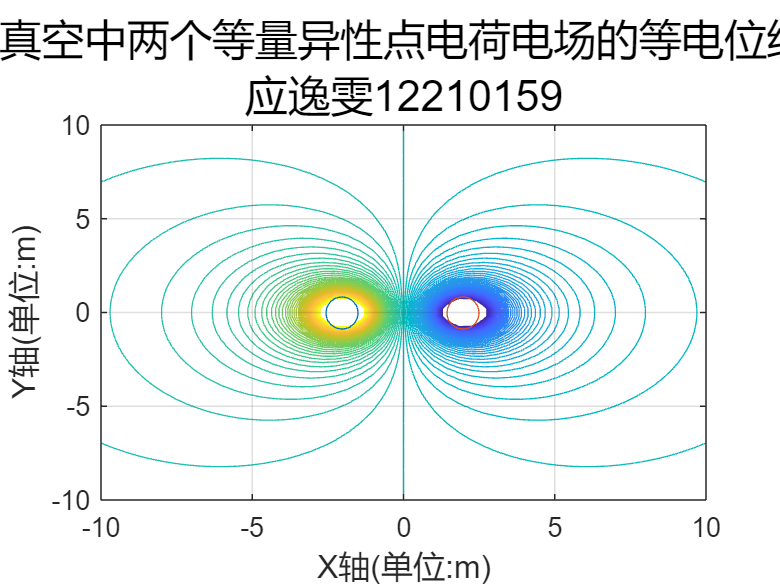

%选择合适的等电位值
Vmin=-50;
Vmax=50;
Veq=linspace(Vmin,Vmax,101);
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);
grid on;
hold on;
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title('真空中两个等量异性点电荷电场的等电位线','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图2-2.jpg');

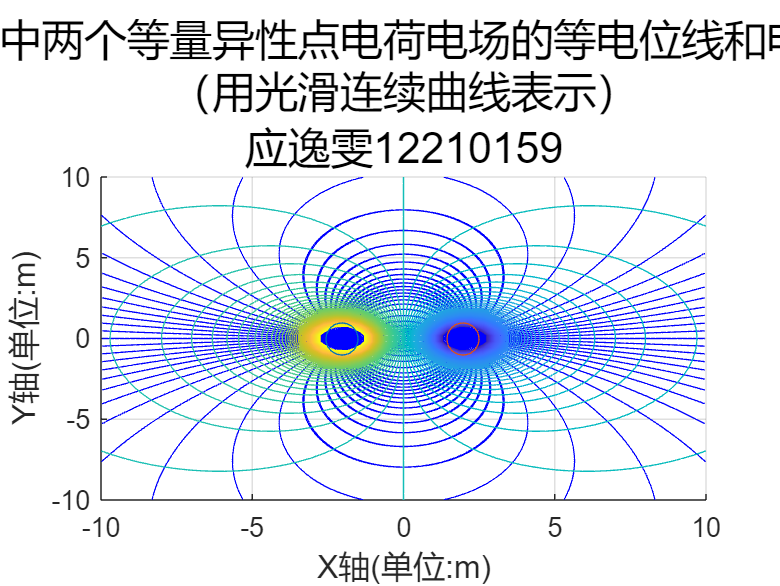

%计算电场线
[Ex,Ey]=gradient(-V);
del_theta=5;
theta=(0:del_theta:360).*pi/180;
xs1=-2+0.0005*cos(theta);
xs2=2+0.0005*cos(theta);
ys1=0.0005*sin(theta);
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,-Ex,-Ey,xs2,ys1);
grid on;
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量异性点电荷电场的等电位线和电力线\n（用光滑连续曲线表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图2-3.jpg');

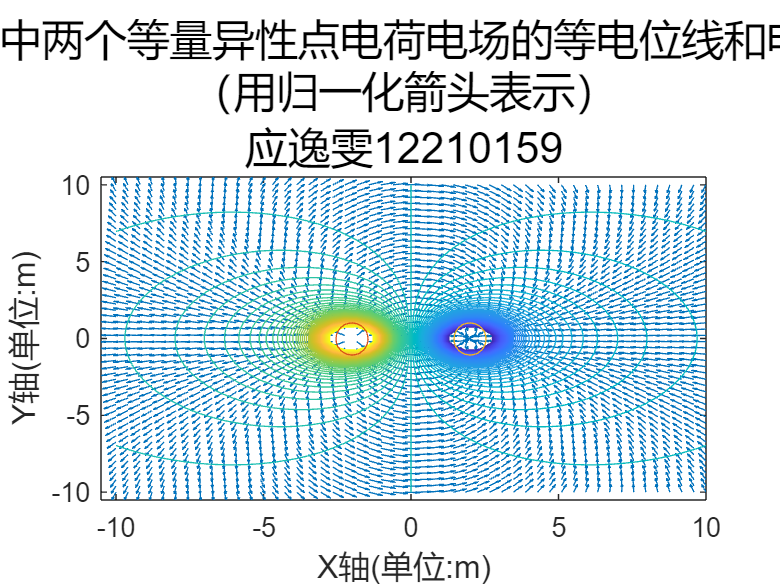

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);
Ex=Ex./E;
Ey=Ey./E;
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量异性点电荷电场的等电位线和电力线\n（用归一化箭头表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图2-4.jpg');

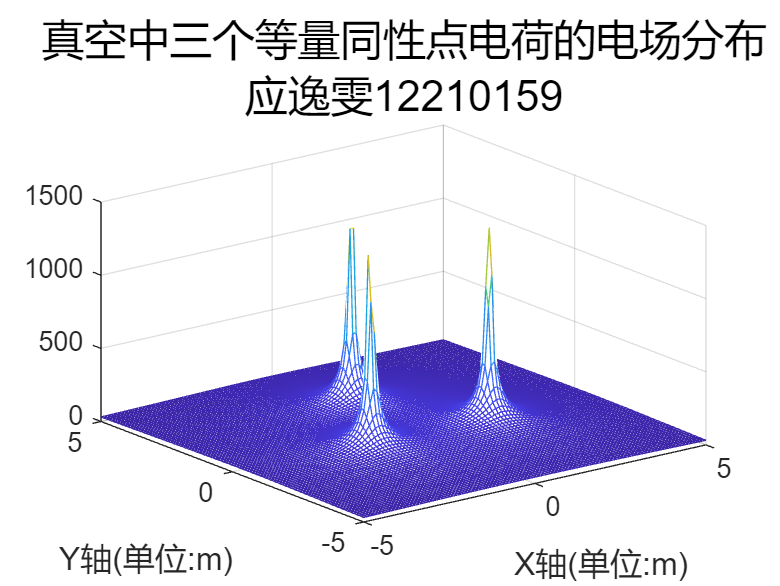

clc,clear,close all;
%位于等边三角形顶点的三个等量同性点电荷的电场分布
%选择场域范围
k=9e9;
Q=8e-9;
xm=5;
ym=5;
x=linspace(-xm,xm,100);
y=linspace(-ym,ym,100);
[X,Y]=meshgrid(x,y);
%计算各点电位
R1=sqrt((X+sqrt(3)).^2+(Y+1).^2);
R2=sqrt((X-sqrt(3)).^2+(Y+1).^2);
R3=sqrt(X.^2+(Y-2).^2);
V=k*Q./R1+k*Q./R2+k*Q./R3;
%绘制各点电位分布
figure;
mesh(X,Y,V);
hold on;
%图表注释
title('真空中三个等量同性点电荷的电场分布','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图3-1.jpg');

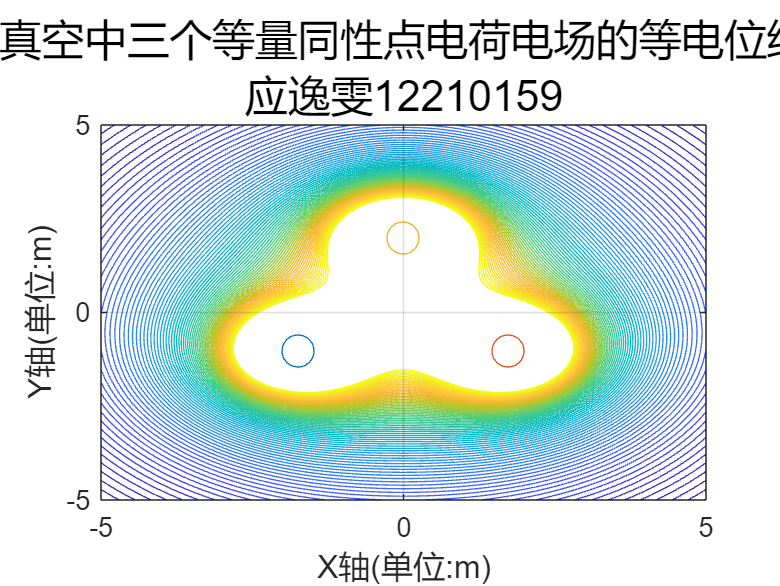

%选择合适的等电位值
Vmin=10;
Vmax=100;
Veq=linspace(Vmin,Vmax,101);
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);
grid on;
hold on;
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title('真空中三个等量同性点电荷电场的等电位线','应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图3-2.jpg');

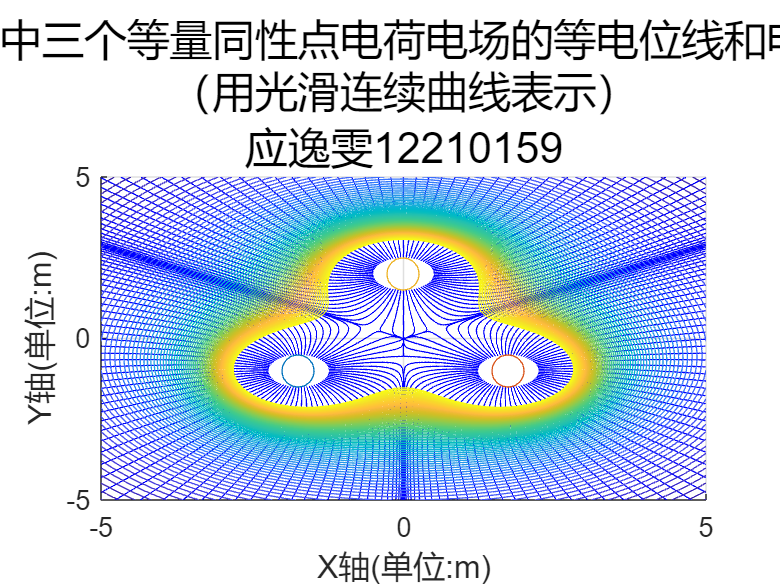

%计算电场线
[Ex,Ey]=gradient(-V);
del_theta=5;
theta=(0:del_theta:360).*pi/180;
xs1=-sqrt(3)+0.5*cos(theta);
xs2=sqrt(3)+0.5*cos(theta);
xs3=0.5*cos(theta);
ys1=-1+0.5*sin(theta);
ys2=-1+0.5*sin(theta);
ys3=2+0.5*sin(theta);
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex,Ey,xs2,ys2);
streamline(X,Y,Ex,Ey,xs3,ys3);
grid on;
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中三个等量同性点电荷电场的等电位线和电力线\n（用光滑连续曲线表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图3-3.jpg');

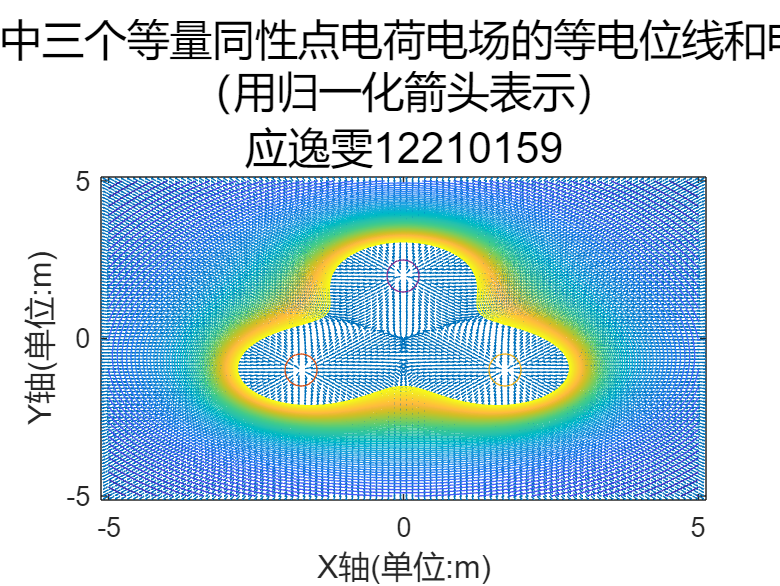

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);
Ex=Ex./E;
Ey=Ey./E;
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中三个等量同性点电荷电场的等电位线和电力线\n（用归一化箭头表示）'),'应逸雯12210159','FontSize',16);
xlabel('X轴(单位:m)','FontSize',12);
ylabel('Y轴(单位:m)','FontSize',12);
%保存图片
saveas(gcf,'图3-4.jpg');